%% Define Constants
m = 285;
Iz = 100;
g = 9.81;
x1 = 0.7675;
x2 = -0.7675;
y1 = 0.6475;
y2 = 0.6285;
z = 0.1816;
C = [1.2801 23.99 0.52 0.003 0.0000];
N_bp = [200 400 600 900 1000 1200];
C_tb = [15000 20000 25000 30000 30000 30000];

X = [x1 x1 x2 x2];
Y = [y1 y1 y2 y2];
R = sqrt(X.^2 + Y.^2);
t = atan([y1/x1 x1/y1 -x2/y2 -y2/x2]);

% Get Dynamic Equation
[r_dot_eqnF, v_dot_eqnF, r_dot_0, v_dot_0, F_eqn, F_non, var] = get_rv_ss(m, Iz, x1, x2);

% Setup Solver
u_vec = 5:15;
d_vec = (-pi/10):(pi/30):0;

% u_vec = [20];
% d_vec = [pi/100];

nx = length(u_vec);
ny = length(d_vec);

[u_grid, d_grid] = meshgrid(u_vec, d_vec);
u_all = u_grid(:);
d_all = d_grid(:);
n = length(d_all);
r_all = zeros(n, 1);

J = 10;
sol_step = zeros(4,J);

% get yaw rate for all sample points
for i = 1:n
    u = u_all(i);
    d = d_all(i);

    ax = 0;
    ay = 0.1;
    r = ay/u;
    v = 0.1;

    aux = [ax;ay];
    val = [0;0;0;0;0;0;0;0;0;0;u;d;r;v];
    
    for j = 1:10
        N = double(compute_N(aux, m, g, x1, x2, y1, y2, z)); 
        val = compute_C(N_bp, C_tb, N, val);
        Fy_max = compute_Fy_max(R, t, val(13), val(14), u, d, N, C);
        [Fy_nom, val] = compute_Fy_nom(r_dot_0, v_dot_0, F_non, var, val);
        [val, aux, sol] = compute_r(r_dot_eqnF, v_dot_eqnF, F_eqn, Fy_nom, Fy_max, val, var, aux);
        sol_step(:,j) = sol;
    end

    r_all(i) = sol(1);

    % figure(1)
    % plot(sol_step(2,:))
    % hold on
    % plot(sol_step(4,:))
    % legend("")
    % 
    % figure(2)
    % plot(sol_step(1,:))
    % hold on
    % plot(sol_step(3,:))
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

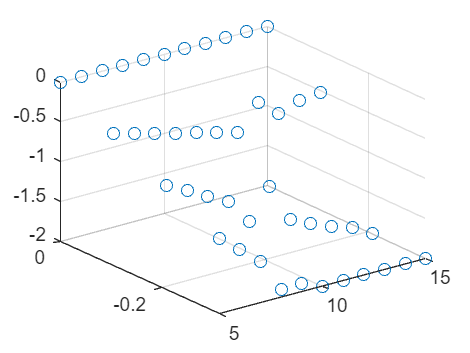


r_grid = reshape(r_all, [ny nx]);

%% Plotting
scatter3(u_all, d_all, max(min(r_all, 2),-2))

function [r_dot_eqn, v_dot_eqn, r_dot_0, v_dot_0, F_eqn, F_non, var] = get_rv_ss(m, Iz, x1, x2)
    %% Define State Symbolics
    r_dot = sym("r_dot",[1 1], "real");
    v_dot = sym("v_dot",[1 1], "real");
    r = sym("r",[1 1], "real");
    v = sym("v",[1 1], "real");
    C = sym("C",[4 1], "real");
    F = sym("F",[4 1], "real");
    
    %% Define Control Symbolics
    u = sym("u", [1 1], "real");
    d = sym("d", [1 1], "real");

    %% Define Symbolic Vector
    var = [r_dot; v_dot; F;  C; u; d; r; v];

    % r_dot_eqn = r_dot == (((-x1*Cf)-(x2*Cr))/(u))*v + (((-x1^2*Cf)-(x2^2*Cr))/(u))*r + ((x1*Cf))*d;
    % v_dot_eqn = v_dot == (((-Cf)-(Cr))/(m*u))*v + (((-x1*Cf)-(x2*Cr))/(m*u))*r -(u*r) + ((Cf)/m)*d;
    % r_dot_0 = 0 == (((-x1*Cf)-(x2*Cr))/(u))*v + (((-x1^2*Cf)-(x2^2*Cr))/(u))*r + ((x1*Cf))*d;
    % v_dot_0 = 0 == (((-Cf)-(Cr))/(m*u))*v + (((-x1*Cf)-(x2*Cr))/(m*u))*r -(u*r) + ((Cf)/m)*d;

    %% Define Lateral Forces
    F1 = C(1)*(d-atan((v+x1*r)/u));
    F2 = C(2)*(d-atan((v+x1*r)/u));
    F3 = C(3)*(-atan((v+x2*r)/u));
    F4 = C(4)*(-atan((v+x2*r)/u));
    F_non = [F1; F2; F3; F4];
    F_eqn = F == F_non;

    % The Dynamics
    r_dot_eqn = Iz*r_dot == x1*(F(1) + F(2)) + x2*(F(3) + F(4));
    v_dot_eqn = m*(v_dot + u*r) == F(1) + F(2) + F(3) + F(4);
    r_dot_0 = 0 == x1*(F1 + F2) + x2*(F3 + F4);
    v_dot_0 = 0 == -m*u*r + F1 + F2 + F3 + F4;
end

function N = compute_N(aux, m, g, x1, x2, y1, y2, z)
    %% Find Minimum Energy Solution
    H = eye(4);
    f = [];
    A = [];
    b = [];
    Aeq = [1 1 1 1; y1 -y1 y2 -y2; x1 x1 x2 x2];
    beq = [m*g; -m*z*aux(2); -m*z*aux(1)];
    % lb = [0; 0; 0; 0];
    lb = [];
    ub = [];
    
    N = quadprog(H,f,A,b,Aeq,beq,lb,ub);
end

function val = compute_C(N_bp, C_tb, N, val)
    val(7:10) = pchip(N_bp, C_tb, N);
end

function Fy_max = compute_Fy_max(R, t, r, v, u, d, N, C)
    % compute beta
    gs = sqrt(u^2 + v^2);
    beta = acos(u / gs);
    
    % compute slip angle
    alpha_fl = d - atan((u*beta + r*R(1)*cos(t(1)))/(u - r*R(1)*sin(t(1))));
    alpha_fr = d - atan((u*beta + r*R(2)*sin(t(2)))/(u + r*R(2)*cos(t(2))));
    alpha_rl = - atan((u*beta - r*R(3)*sin(t(3)))/(u - r*R(3)*cos(t(3))));
    alpha_rr = - atan((u*beta - r*R(4)*sin(t(4)))/(u + r*R(4)*cos(t(4))));
    alpha = [alpha_fl; alpha_fr; alpha_rl; alpha_rr];

    % compute slip
    Ss = tan(alpha);
    Sl = [0; 0; 0; 0];
    Sres = sqrt(Ss.^2 + Sl.^2);

    % compute mu
    mu = (C(1).*(1-exp(-C(2).*Sres))-C(3).*Sres).*exp(C(4)*Sres*gs).*(1-C(5).*N.^2);

    % compute Fy_max
    Fy_max = mu.*N;
end

function [Fy_nom, val] = compute_Fy_nom(r_dot_0, v_dot_0, F_non, var, val)
    r_eqn = subs(r_dot_0, var(7:12), val(7:12));
    v_eqn = subs(v_dot_0, var(7:12), val(7:12));

    sol = vpasolve([r_eqn; v_eqn]);
    val(13:14) = double([sol.r1; sol.v1]);

    Fy_nom = double(subs(F_non, var(7:14), val(7:14)));
end

function [val, aux, sol] = compute_r(r_dot_eqnF, v_dot_eqnF, F_eqn, Fy_nom, Fy_max, val, var, aux)
    % Determine number of tires that are slipping
    slipping = abs(Fy_max) < abs(Fy_nom);

    % Get Lateral Force
    Fy = [0;0;0;0];
    Fy(slipping) = Fy_max(slipping);
    Fy(~slipping) = Fy_nom(~slipping);
    val(3:6) = Fy;

    % Form Equations
    r_dot_eqn_filled = subs(r_dot_eqnF, var([3 4 5 6 11]), [Fy; val(11)]);
    v_dot_eqn_filled = subs(v_dot_eqnF, var([3 4 5 6 11]), [Fy; val(11)]);
    F_eqn_filled = subs(F_eqn, var(3:12), val(3:12));
    all_eqn = [r_dot_eqn_filled; v_dot_eqn_filled; F_eqn_filled];

    eqn_1 = all_eqn([1 2 3 5]);
    eqn_2 = all_eqn([1 2 4 6]);
        
    % solve equations
    sol_1 = vpasolve(eqn_1);
    sol_2 = vpasolve(eqn_2);

    sol_1 = double([sol_1.r1; sol_1.r_dot1; sol_1.v1; sol_1.v_dot1]);
    sol_2 = double([sol_2.r1; sol_2.r_dot1; sol_2.v1; sol_2.v_dot1]);
    sol = (sol_1 + sol_2) ./ 2;

    % update values
    val(13) = sol(1) + sol(4)/val(11);
    val(14) = sol(3);

    % update auxillary
    aux(2) = val(11)*val(13) + sol(4);
end